aucC = 0.0717

aucD = 0.0604

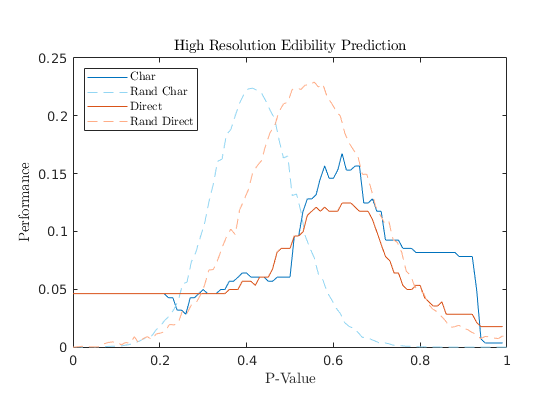

aucC = 0.0795

aucD = 0.0926

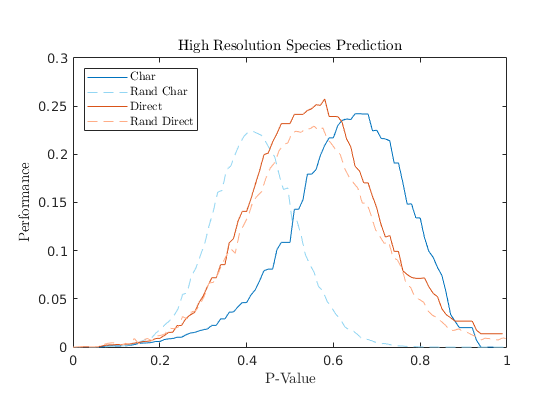

aucC = 0.0723

aucD = 0.0638

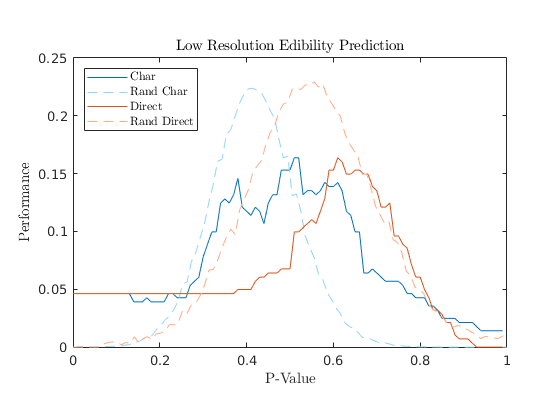

aucC = 0.0875

aucD = 0.1039

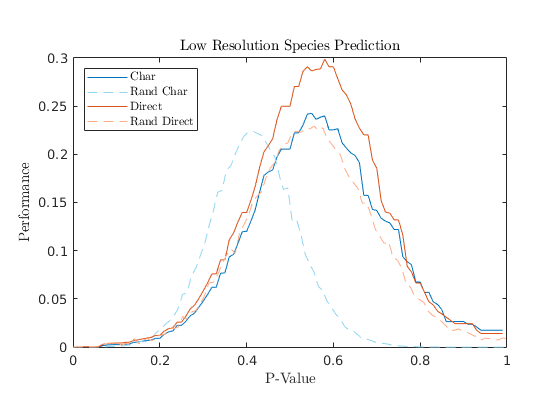

files = dir("performance_data/*_perform.csv");
names = string.empty(length(files), 0);
for i = 1:length(files);
    names(i) = files(i).name;
end
names = names';
cfiles = names(contains(names, "characteristic"));
clen = length('characteristic');
dfiles = names(contains(names, "direct"));
dlen = length('direct');

for i= 1:length(cfiles)
    cf = cfiles(i);
    suffix = cf{1}(clen+1:end);
    df = dfiles(dfiles == "direct" + suffix);
    PC = readmatrix("performance_data/" + cf)';
    PD = readmatrix("performance_data/" + df)';
    PB = readmatrix("performance_data/baseline_perform.csv")';
    PS = readmatrix("performance_data/random_species_perform.csv")';
    
    figure
    plotP(PC, PD, PB, PS, "");
    title(title_from_suffix(suffix))
    saveas(gcf, "plots/" + replace(title_from_suffix(suffix), newline, "") + ".png")
end

% > EXPECTATIONS
PP = readmatrix("performance_data/perfect_perform.csv")';
PS = readmatrix("performance_data/random_species_perform.csv")';
plot(PP(:,1), PP(:,2));
hold on
plot(PB(:,1), PB(:,2));
plot(PS(:,1), PS(:,2));
hold off

aucP = trapz(PP(:,1), PP(:,2))

aucP = 0.4547

aucP = sum(PP(:,2))

aucP = 45.9702

aucB = trapz(PB(:,1), PB(:,2))

aucB = 0.0535

aucS = trapz(PS(:,1), PS(:,2))

aucS = 0.0817

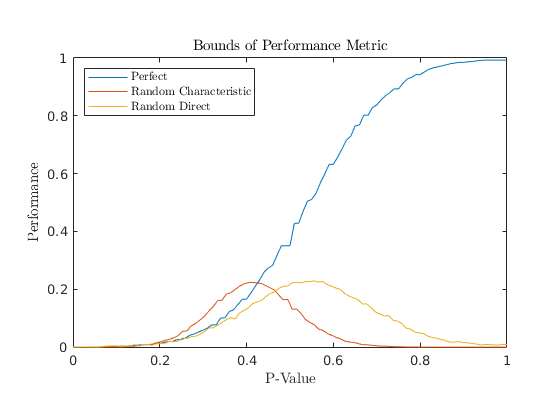


xlabel("P-Value", "Interpreter","latex");
ylabel("Performance", "Interpreter","latex");
title("Bounds of Performance Metric", "Interpreter","latex");
l = legend("Perfect",...+newline+"AUC="+aucP,...
    "Random Characteristic",...+newline+"AUC="+aucB,...
    "Random Direct",...+newline+"AUC="+aucS,...
    "Location","northwest", "Interpreter","latex");
pbaspect([1.5,1,1])
saveas(gcf, "plots/Perfect Performance.png")

function plotP(PC, PD, PB, PS, name)
plot(PC(:,1), PC(:,2), "Color", '#0072BD');
hold on
plot(PB(:,1), PB(:,2), '--', "Color",1-[0.8500 0.3250 0.0980]*.5);
plot(PD(:,1), PD(:,2), "Color", '#D95319');
%     brighten(0.1)
plot(PS(:,1), PS(:,2), '--', "Color",1-[0 0.6470 0.9410]*.5);
hold off
xlabel("P-Value", "Interpreter","latex");
ylabel("Performance", "Interpreter","latex");
aucC = trapz(PC(:,1), PC(:,2))
aucD = trapz(PD(:,1), PD(:,2))
aucB = trapz(PB(:,1), PB(:,2));
aucS = trapz(PS(:,1), PS(:,2));

title(name, "Interpreter","latex");
l = legend(["Char",...+newline+"AUC="+aucC, ...
    "Rand Char",...+newline+"AUC="+aucB,...
    "Direct",...+newline+"AUC="+aucD,...
    "Rand Direct",...+newline+"AUC="+aucS,...
    ], "Location","northwest", "Orientation","vertical", "Interpreter","latex");
%     ], "Location","southoutside", "Orientation","horizontal");
        

% l.Units = "pixels";
f = gcf;
a = gca;
a.Units = "pixels";
% f.Position(3) = 600;
% oldheight = f.Position(4);
% f.Position(4) = f.Position(4) + l.Position(4);
% a.Position(4) = oldheight - l.Position(4);
pbaspect([1.5,1,1])
% l.Position(1) = 0.1;
% f.Position(3) = f.Position(3) + l.Position(3);
end
function tit = title_from_suffix(suffix)
tit = "";
suffix = string(suffix);
if contains(suffix, "_bolete.h5")
    tit = tit + "High Resolution";
else
    tit = tit + "Low Resolution";
end
if contains(suffix, "_ed")
    tit = tit + " Edibility Prediction";
else
    tit = tit + " Species Prediction";
end
end